clc;
clear;
close all;

% 1. Parameters

L  = 1.0;   % Plate length (m)
H  = 0.5;   % Plate height (m)

nx = 20;   % Number of divisions in x
ny = 10;   % Number of divisions in y

k0    = 200;  % Base thermal conductivity
alpha = 0.1;  % Conductivity variation in x
beta  = 0.05;  % Conductivity variation in y

h      = 0;  % Convection coefficient
T_inf  = 300; % Ambient temperature
T_left = 400; % Left edge temperature

tol = 1e-12;

% 2. Generating Nodes

dx = L/nx;
dy = H/ny;

nodes = [];

for j = 0:ny

    for i = 0:nx

        x = i*dx;
        y = j*dy;

        nodes = [nodes; x y];

    end

end

nodes

nodes =          0         0
    0.0500         0
    0.1000         0
    0.1500         0
    0.2000         0
    0.2500         0
    0.3000         0
    0.3500         0
    0.4000         0
    0.4500         0


num_nodes = size(nodes,1)

num_nodes = 231



% 3. Generating triangular elements

elements = [];

for j = 1:ny

    for i = 1:nx

        n1 = (j-1)*(nx+1) + i;
        n2 = n1 + 1;

        n4 = j*(nx+1) + i;
        n3 = n4 + 1;

        % Triangle 1
        elements = [elements; n1 n2 n3];

        % Triangle 2
        elements = [elements; n1 n3 n4];

    end

end

elements

elements =      1     2    23
     1    23    22
     2     3    24
     2    24    23
     3     4    25
     3    25    24
     4     5    26
     4    26    25
     5     6    27
     5    27    26


num_elements = size(elements,1)

num_elements = 400

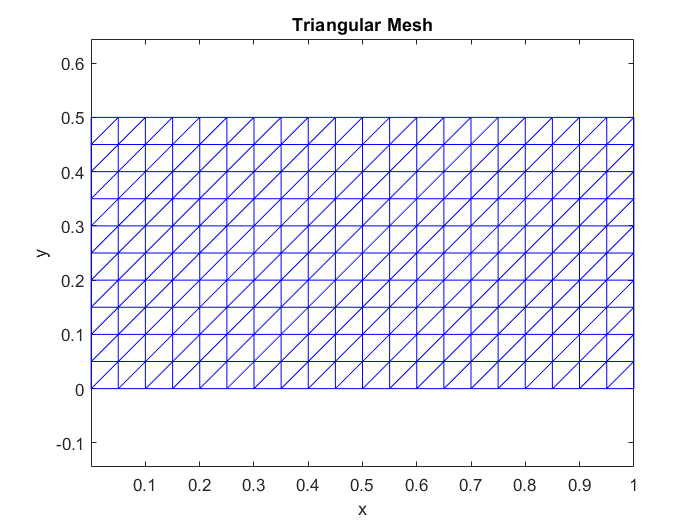



% 4. Plotting triangular mesh

figure

triplot(elements, nodes(:,1), nodes(:,2),'b')

axis equal

xlabel('x')
ylabel('y')

title('Triangular Mesh')



% 5. Initialize the global matrices

K = zeros(num_nodes,num_nodes);

F = zeros(num_nodes,1);


% 6. Element loops 

for e = 1:num_elements

    element_nodes = elements(e,:); % element nodes 

    % Coordinates of nodes
    x1 = nodes(element_nodes(1),1);
    y1 = nodes(element_nodes(1),2);

    x2 = nodes(element_nodes(2),1);
    y2 = nodes(element_nodes(2),2);

    x3 = nodes(element_nodes(3),1);
    y3 = nodes(element_nodes(3),2);

    
    % Jacobian Matrix

    dx_dxi  = (-0.5*x1) + (0.5*x2);
    dy_dxi  = (-0.5*y1) + (0.5*y2);

    dx_deta = (-0.5*x2) + (0.5*x3);
    dy_deta = (-0.5*y2) + (0.5*y3);

    J = [dx_dxi   dy_dxi; dx_deta  dy_deta];

    detJ = det(J);

    invJ = inv(J);

    
    % Shape function derivatives wrt xi and eta
    
    dN_dxi = [-0.5; 0.5; 0.0];

    dN_deta = [0.0; -0.5; 0.5];

    % Derivatives wrt x and y [B]

    gradN = invJ * [dN_dxi'; dN_deta'];

    dN_dx = gradN(1,:);
    dN_dy = gradN(2,:);

    % B matrix

    B = [dN_dx; dN_dy];

     
    % Gauss Point

    xi  = 1/3;
    eta = -1/3;

    weight = 2;

    % Shape functions at Gauss point

    N1 = 0.5*(1 - xi);

    N2 = 0.5*(xi - eta);

    N3 = 0.5*(1 + eta);

    N = [N1 N2 N3];

    
    % Coordinates at Gauss point   

    x_gp = N*[x1; x2; x3];

    y_gp = N*[y1; y2; y3];

    % Spatially variable thermal conductivity
  
    k = k0*(1 + alpha*x_gp + beta*y_gp);

    
    % Element stiffness matrix

    Ke = (B'*k*B)*detJ*weight;
    

    % Assembly

    for i = 1:3

        for j = 1:3

            K(element_nodes(i), element_nodes(j)) = K(element_nodes(i), element_nodes(j)) + Ke(i,j);
            

        end

    end
    K;

end


% 7. Apply convection boundary condition 

for e = 1:num_elements

    element_nodes = elements(e,:);

    edge_list = [1 2; 2 3; 3 1];

    for edge = 1:3

        local_nodes = edge_list(edge,:);

        n1 = element_nodes(local_nodes(1));
        n2 = element_nodes(local_nodes(2));

        p1 = nodes(n1,:);
        p2 = nodes(n2,:);

        % TOP EDGE

        if abs(p1(2)-H)<tol && abs(p2(2)-H)<tol

            Le = norm(p2-p1);

            Kh = h*Le/6 * [2 1; 1 2];

            Fh = h*T_inf*Le/2 * [1; 1];

            edge_nodes = [n1 n2];

            K(edge_nodes,edge_nodes) = K(edge_nodes,edge_nodes) + Kh;

            F(edge_nodes) = F(edge_nodes) + Fh;

        end

        % RIGHT EDGE

        if abs(p1(1)-L)<tol && abs(p2(1)-L)<tol

            Le = norm(p2-p1);

            Kh = h*Le/6 * [2 1; 1 2];

            Fh = h*T_inf*Le/2 * [1; 1];

            edge_nodes = [n1 n2];

            K(edge_nodes,edge_nodes) = K(edge_nodes,edge_nodes) + Kh;

            F(edge_nodes) = F(edge_nodes) + Fh;

        end

    end

end



% 8. Apply dirichlet boundary condition

left_nodes = [];

for i = 1:num_nodes

    if abs(nodes(i,1)) < tol

        left_nodes = [left_nodes; i];

    end

end

for i = 1:length(left_nodes)

    node = left_nodes(i);

    F = F - K(:,node)*T_left;

    K(node,:) = 0;
    K(:,node) = 0;

    K(node,node) = 1;

    F(node) = T_left;

end
F;

% 9. Solving system of equations

T = K\F;
T

T =   400.0000
  400.0000
  400.0000
  400.0000
  400.0000
  400.0000
  400.0000
  400.0000
  400.0000
  400.0000


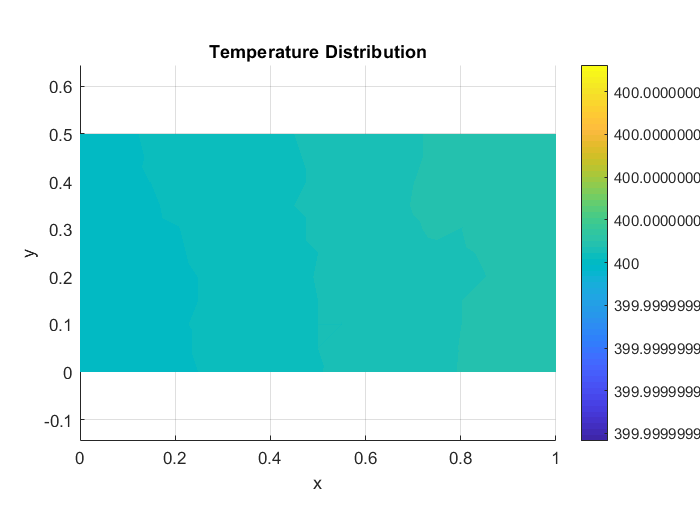


% 10. Temperature contour plot

figure

trisurf(elements, nodes(:,1), nodes(:,2), T, 'EdgeColor','none')

view(2)

axis equal

xlabel('x')
ylabel('y')

title('Temperature Distribution')

colorbar

shading interp


% 11. Post Processing and results

fprintf('Maximum Temperature = %.2f K\n',max(T));

Maximum Temperature = 400.00 K



fprintf('Minimum Temperature = %.2f K\n',min(T));

Minimum Temperature = 400.00 K




% 12. Boundary Heat Flux Calculation

Q_total = 0;

for e = 1:num_elements

    element_nodes = elements(e,:);

    edge_list = [1 2; 2 3; 3 1];

    for edge = 1:3

        local_nodes = edge_list(edge,:);

        n1 = element_nodes(local_nodes(1));
        n2 = element_nodes(local_nodes(2));

        p1 = nodes(n1,:);
        p2 = nodes(n2,:);

        
        % Top edge convection

        if abs(p1(2)-H)<tol && abs(p2(2)-H)<tol
            
            Le = norm(p2-p1); % edge length 

            % 1-point Gauss quadrature
            xi = 0;
            weight = 2;

            % Shape functions at Gauss point
            N1 = 0.5*(1-xi);
            N2 = 0.5*(1+xi);

            Nedge = [N1 N2];

            Te = [T(n1); T(n2)]; % Edge nodal temperatures

            T_gp = Nedge*Te; % Temperature at Gauss point

            q = h*(T_gp - T_inf); % Boundary heat flux

            J_edge = Le/2; % Jacobian for line element

            Qe = q*J_edge*weight; % Heat transfer through edge

            Q_total = Q_total + Qe; % Total heat transfer

            fprintf('Top Edge (%d-%d): q = %.4f W/m^2\n', n1,n2,q);

        end

        % Right convection edge 

        if abs(p1(1)-L)<tol && abs(p2(1)-L)<tol

            Le = norm(p2-p1);
            
            xi = 0;
            weight = 2;

            N1 = 0.5*(1-xi);
            N2 = 0.5*(1+xi);

            Nedge = [N1 N2];

            Te = [T(n1); T(n2)];

            T_gp = Nedge*Te;

            q = h*(T_gp - T_inf);

            J_edge = Le/2;

            Qe = q*J_edge*weight;

            Q_total = Q_total + Qe;

            fprintf('Right Edge (%d-%d): q = %.4f W/m^2\n', n1,n2,q);

        end

    end

end

Right Edge (21-42): q = 0.0000 W/m^2
Right Edge (42-63): q = 0.0000 W/m^2
Right Edge (63-84): q = 0.0000 W/m^2
Right Edge (84-105): q = 0.0000 W/m^2
Right Edge (105-126): q = 0.0000 W/m^2
Right Edge (126-147): q = 0.0000 W/m^2
Right Edge (147-168): q = 0.0000 W/m^2
Right Edge (168-189): q = 0.0000 W/m^2
Right Edge (189-210): q = 0.0000 W/m^2


Top Edge (212-211): q = 0.0000 W/m^2
Top Edge (213-212): q = 0.0000 W/m^2
Top Edge (214-213): q = 0.0000 W/m^2
Top Edge (215-214): q = 0.0000 W/m^2
Top Edge (216-215): q = 0.0000 W/m^2
Top Edge (217-216): q = 0.0000 W/m^2
Top Edge (218-217): q = 0.0000 W/m^2
Top Edge (219-218): q = 0.0000 W/m^2
Top Edge (220-219): q = 0.0000 W/m^2
Top Edge (221-220): q = 0.0000 W/m^2
Top Edge (222-221): q = 0.0000 W/m^2
Top Edge (223-222): q = 0.0000 W/m^2
Top Edge (224-223): q = 0.0000 W/m^2
Top Edge (225-224): q = 0.0000 W/m^2
Top Edge (226-225): q = 0.0000 W/m^2
Top Edge (227-226): q = 0.0000 W/m^2
Top Edge (228-227): q = 0.0000 W/m^2
Top Edge (229-228): q = 0.0000 W/m^2
Top Edge (230-229): q = 0.0000 W/m^2


Right Edge (210-231): q = 0.0000 W/m^2


Top Edge (231-230): q = 0.0000 W/m^2



fprintf('\nTotal Convective Heat Transfer = %.4f W\n',Q_total);


Total Convective Heat Transfer = 0.0000 W
